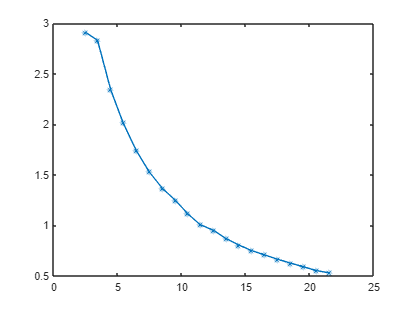

actual = zeros(20,1);
measured = zeros(20,1);
for n= 1:length(pD3_B)
    actual(n,:)= mean([pD1_B(n,1),pD2_B(n,1),pD3_B(n,1)]);
    measured(n,:) = mean([pD1_B(n,2),pD2_B(n,2),pD3_B(n,2)]);
end
plot(actual,measured,'-*')

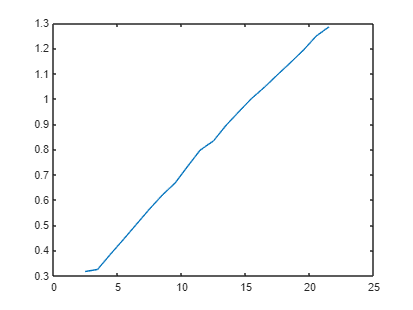

%linearization
lin_V = 1./(measured+0.25);
plot(actual,lin_V)

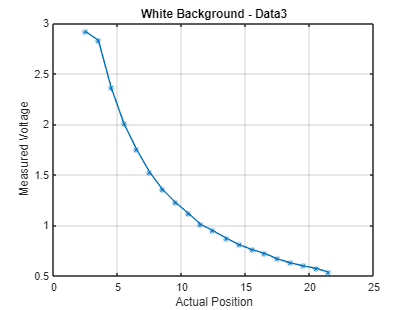

pD3_W = positionData;
save pD3_W

plot(pD3_W(:,1), pD3_W(:,2),'-*')
xlabel('Actual Position')
ylabel('Measured Voltage')
title('White Background - Data3')
grid